# Racing Line Optimizer

### Import track data

%track = readmatrix("Silverstone.csv")
track = readmatrix("yasmarina_converted.csv")

track =     0.1360   -0.1352    7.2696    7.2696
    5.3684    0.6412    7.2972    7.2972
   10.6010    1.4149    7.3225    7.3225
   15.8337    2.1858    7.3455    7.3455
   21.0667    2.9542    7.3664    7.3664
   26.2999    3.7202    7.3853    7.3853
   31.5332    4.4838    7.4023    7.4023
   36.7668    5.2453    7.4175    7.4175
   42.0005    6.0047    7.4311    7.4311
   47.2344    6.7622    7.4431    7.4431


### Define variables

%trackName = 'Silverstone';
trackName = 'YasMarina';
m = 750; % Mass of vehicle
ftmax = 16; % Max acceleration (m/s^2)
fbmax = 18; % Min acceleration (m/s^2)
fnmax = 30; % Max cornering acceleration (m/s^2)

### Generate optimized path

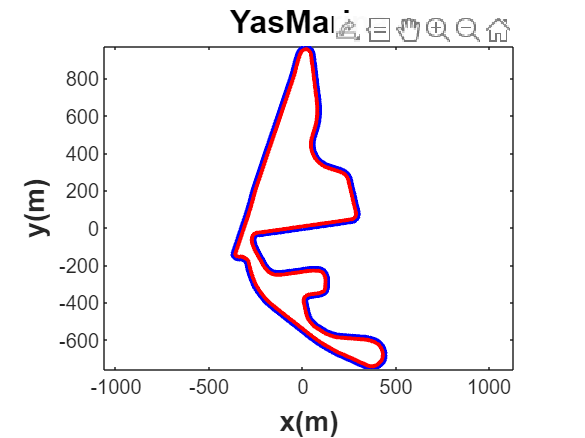

 Iter            Fval  Primal Infeas    Dual Infeas  Complementarity  
    0   -1.735377e+00   0.000000e+00   2.514927e+02     1.000000e+00  
    1   -5.190765e+01   1.110223e-16   1.257464e-01     2.502501e-01  
    2   -5.319659e+01   0.000000e+00   2.980354e-03     3.078270e-02  
    3   -5.488985e+01   0.000000e+00   4.083670e-05     3.211532e-03  
    4   -5.531846e+01   4.773959e-15   3.569456e-06     3.998323e-04  
    5   -5.534244e+01   1.776357e-15   1.551754e-06     1.351388e-04  
    6   -5.534703e+01   7.771561e-16   5.599258e-07     6.322780e-05  
    7   -5.534857e+01   2.220446e-16   8.690901e-08     2.614601e-05  
    8   -5.534877e+01   0.000000e+00   1.572910e-08     4.446071e-06  
    9   -5.534879e+01   0.000000e+00   3.876234e-09     1.121500e-06  
   10   -5.534879e+01   0.000000e+00   5.383533e-10     1.534142e-07  
   11   -5.534879e+01   0.000000e+00   1.589797e-12     5.287795e-10  



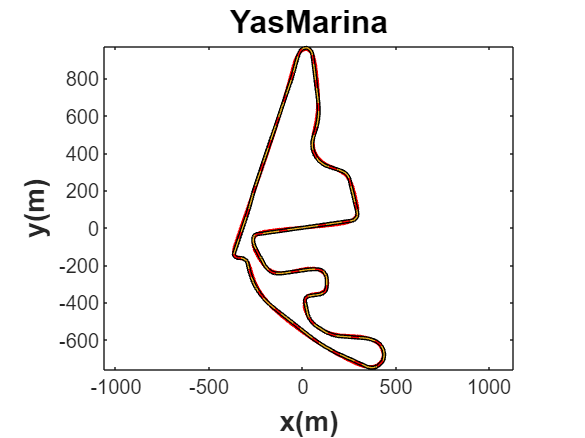

[trajMCP, trackData] = minCurvaturePathGenFunction(track,trackName);

% Click on the drop down menu to select the method for generating the optimized path

### Generate velocity profile

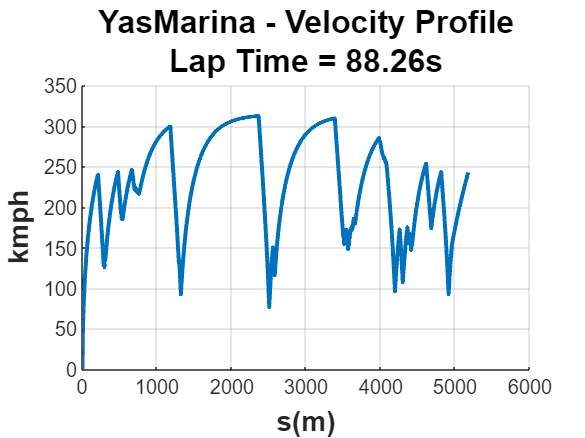

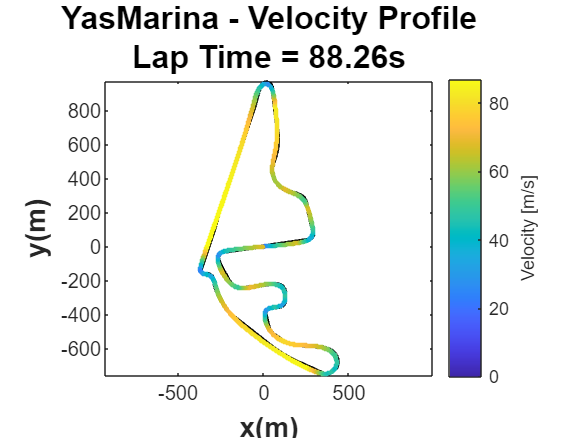

[velProf,len] = velProfCalcFunction(trajMCP,trackName,m,ftmax,fbmax,fnmax,trackData);

### References:

- The Silverstone racetrack data has been ta    ken from the following GitHub repository: [https://github.com/TUMFTM/racetrack-database](https://github.com/TUMFTM/racetrack-database) 

- The function, "velProfCalcFunction" uses the function, "curvature" that has been taken from the following File Exchange: [https://www.mathworks.com/matlabcentral/fileexchange/69452-curvature-of-a-1d-curve-in-a-2d-or-3d-space](https://www.mathworks.com/matlabcentral/fileexchange/69452-curvature-of-a-1d-curve-in-a-2d-or-3d-space) 